This is a tutorial on basic cognitive model fitting to behavioural data from a decision task.

We're taking a standard dot-motion discrimination task as an example, using data from Janik Wiese's project in 2022/23, where subjects responded with a left/right hand button press as fast and as accurately as possible, for leftward/rightward motion in a noisy dot stimulus that appeared against a blank background. In different blocks they had different mixes of difficulty levels (coherence). We're going to analyse 'regime 2' which had 4 randomly interleaved coherence levels [6 14 26 48]%, and address the question of whether a drift diffusion model (see e.g. Ratcliff et al 2016) fits the data better when it allows a 'collapsing bound' over time relative to a constant bound. Since the latter model is 'nested' within (i.e. a special case of) the former, the quantitative fit (how close model-predicted data are to real data) can only be better for the more complex collapsing-bound model just by virtue of it being the same but with additional free parameter(s) - and this provides a sanity check in that if this is not the case we'll know we've done something wrong - so our metric for determining 'best' model will be something that penalises for complexity - we'll compute AIC and BIC here. Hawkins et al (2015) is a good example of a study pursuing this question.

In Janik's task, the dots are presented for a maximum of 1.5 sec which serves as a deadline, and no responses later than that are logged. Also RTs<250 ms get feedback "too early" and though any such RT would have been logged, subjects never actually made RT<250 ms.

minRT = 0.25;
maxRT = 1.5;
cohlevels = [6 14 26 48];
% read the behavioural data in:
load('data_allsubj.mat')
% the behavioural data matrix should contain one row for each trial, and at least these 3 columns:
% col 1: condition (integers referring to different conditions. 
% col 2: trial outcome (1=correct, 0=error, 2=miss if relevant)
% col 3: RT in sec (check it's not ms or EEG samples)

These 3 columns comprise the format commonly used in the field of behavioural modeling. Often this might be the data of a single subject at a time, but for our example the matrix appends the data of several subjects, and we are going to fit our models to the grand average data. In practice studies often fit individuals and then e.g. count up for how many subjects one model was better than another. We'll keep it simple for the tutorial and just fit to grand average.

You should always just look at the raw data before doing anything. e.g. the histogram of ALL RTs:

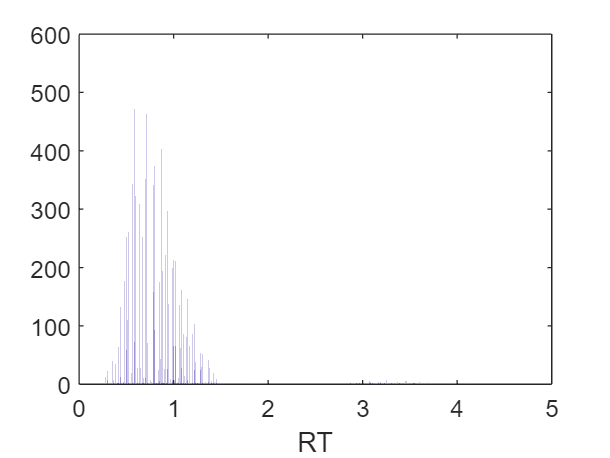

figure; hist(data_allsubj(:,3),[0:.001:5]); xlim([0 5]); xlabel('RT') % note 1-ms resolution

Note the RTs cut-off abruptly at 1.5 sec, but then there are some really long ones >3 sec. This happened because these RTs were extracted from the EEG data by finding the next response that happened after each dot-stimulus onset, and if there was no response during it, it would find the next trial's response. Let's re-cast those as misses:

miss = find(data_allsubj(:,3)>1.5);
data_allsubj(miss,2)=2;
data_allsubj(miss,3)=nan;

Another thing to notice when you zoom in is that the RTs seem quantised, only taking certain values 16.7 ms apart. This happened because EEG triggers for responses were only sent at the one time per monitor refresh when the mouse buttons were checked. The precise RTs were recorded in the psychtoolbox task script in a separate .mat, but let's assume the quantised RTs are precise enough.

Fitting a certain model to data involves searching a multidimensional parameter space (one dimension for each free parameter) to find the parameter vector (set of parameter values) that minimises an 'objective function,' which is a metric that quantifies how divergent the model-predicted data are from the real.

This is performed using 4 functions that, respectively, 

1) construct a data summary to be fit - makeSummaryStructure.m

2) simulates 'predicted data' for a given model and set of parameter values - simul_2AFCddm.m

3) computes the objective function by comparing those predicted data to the real data summary - G2.m

4) performs the search algorithm - here we use a standard matlab function 'particleswarm'

Before getting into implementation I'll explain some of the considerations that play into each:

1) **Data summary.** In our case we want our model to capture how accuracy and RT distributions vary with coherence. Collapsing bounds are associated with a more symmetric than usual RT distribution because the rightward skew is curtailed, and predict relatively high error rates for trials where the subject responded with slower RT. In general you must always summarise the data in a way that represents the essential data patterns/phenomenon of interest, or, like in this case, in a way that should in principle be diagnostic for competing alternative models. In other cases it might not make sense to include RTs (e.g. for delayed-response tasks) or error trials (e.g. pure detection where there is no wrong response), or it might be important to include false alarm rates (e.g. when examining continuous target detection in noise) - always think about what are the essential data patterns to be captured. The data summary then is just a set of numbers that your model being fit needs to try its best to match. 

2) **Simulating predicted data**. This function implements the model. It will take in a set of parameter values in a parameter vector, and possibly some indicator variables to tell it what version of the model to use, and output some predicted data. For many standard models, mathematical derivations have been done to determine a closed-form math expression that gives the RT distributions and accuracy for a given set of parameter values, but we're going to do it a clunkier way, and actually simulate the diffusion process on each of a large number of trials to generate single-trial data in a similar format to the 3 columns above, so that it can be summarised in a similar way to the real data. This is computationally more demanding but has the advantage of flexibility - i.e. what if we come up with a model structure for which there is no closed form solution? we don't want to be precluded from testing it just because no one has done the maths derivations. The simulated single trial data is generated by simul_2AFCddm.m - that stands for 2-alternative forced choice.

3)** Computing the objective function to be minimised**. Here we use a statistic called "G-squared" implemented by the function G2.m. This is a 'multinomial likelihood statistic' computed essentialy by summing up the differences between simulated and real proportions of trials corresponding to each of a set of possible outcomes for each condition of interest. Other alternatives are log-likelihood-based metrics calculated from the single trials, or simpler mean-squared error metrics but G^2 is known to work well for capturing the shapes of RT distributions simply. To explain it fully let's look at the equation for Kelly et al (2021), where there were 9 conditions of interest (3 'regimes' r defined by different settings of speed pressure and coherence, crossed with 3 'validity' conditions v, meaning a preceding cue indicated the correct direction, incorrect direction, or was neutral):

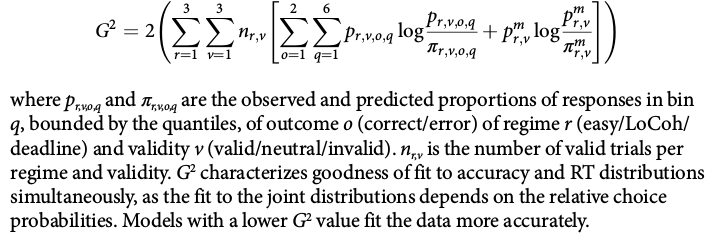

Let's call the observed proportions 'po' and the predicted proportions 'pp' to avoid greek letters.

It's clear from the equation that each condition of interest has its own G^2 contribution to the overall sum, with the contribution given by the bit in square brackets multiplied by the number of trials for that condition. Within the square brackets, the core term po*log(po/pp) is computed for each of a mutually exclusive set of possible outcomes that together comprise everything that could possibly happen for that condition. Here I divided the condition into a total of 13 possible outcomes (note in the paper I used the term 'outcome' for what I should have called 'correctness' - I'm now using the term in a broader sense). Correct responses and error responses are each divided into 6 quantile bins seperated by the 5 RT quantiles [.1 .3 .5 .7 .9] calculated from the real data for that condition and correctness, and then the 13th outcome is no response at all - a miss. Misses are sometimes best just deleted from the data from the start, if they are extremely few or suspected to occur for reasons that aren't worth trying to capture in the model (e.g. subject was distracted or asleep so decision process didn't even happen), but here I include them because I saw that the number of them inversely varies with coherence, and the RT distributions look like they are cut-off abruptly at 1.5 sec, all suggesting these are cases where subjects probably were engaging with the decision and intending to respond but didn't in time. I define them as a 13th outcome category rather than bundling them in with the longest RT bin simply because we don't know whether each miss was destined to be correct or an error. You can define different sets of 'outcomes' depending on your study and questions, e.g. in Geuzebroek et al (2023) we also included proportions of inter-target-interval periods containing a false alarm or not. You can also define more conditions if there are other factors that matter, e.g. if you wanted to specifically examine the influence of correctness of response in the previous trial, you'd expand the conditions to 'post-correct low coherence', 'post-error low coherence' and so on.

According to Ratliff & McKoon (2020), a good rule of thumb is that you can take it that you're getting a generally decent fit if the obtained G^2 value is less than 2 times the critical chi-squared value (assume alpha level of 0.05?) for the degrees of freedom in the data/fit. They say dof for the data is obtained by taking the number of outcomes you've chunked each condition into (13) and subtracting 1, then multiplying by the number of conditions. So for us here this would be 12*4 = 48. And the critical value is icdf('Chisquare',0.95,48) = 65.2. They also say that when fitting the model to the data, the number of free parameters should be subtracted from the degrees of freedom, but it's ambiguous as to whether thy mean that that is the critical value that should be used. This works as a ballpark - you should be looking for a fit that is about G2=120-130 or lower.

4) **an algorithm for performing the search (optimisation) in parameter space**. Two options are SIMPLEX (implemented using a function fminsearchbnd, a version of fminsearch where you specify bounds or limits within which each parameter must lie, to constrain the search) and particle swarm, but there are others, and Bayesian methods. Here we'll use particle swarm. The main challenge with an optimisation algorithm is to avoid getting stuck in local minima and making sure to find a global minimum. The simple trick to that is just starting the search from multiple starting vectors scattered throughout parameter space. When we use SIMPLEX we do this manually, but particle swarm does this implicitly - that's what the different "particles" are.

So let's go for it:

% Make the data summary:
% First define the RT quantiles from which we are going to compute the trial proportions for real and simulated data:
qps = [.1 .3 .5 .7 .9]; % these are quite standard
datsum = makeSummaryStructure(data_allsubj,qps,4); % the 4 indicates the column with a subject indicator, 

 Let's plot the data summary:

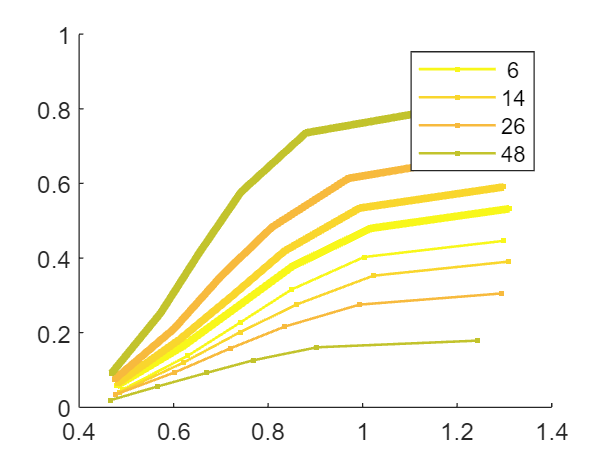

plotdatsum(datsum) % this plots a cumulative distribution, which makes it easy to see the effect of coheren e on RT and accuracy

You can see the RTs are faster and the proportion correct relative to error are larger for higher coherences, as would be expected. 

Next step is to code up the model simulation function and test it. What parameters should it have, in its fullest form? 

Let's say we're interested in just testing a linear collapsing bound, which can be captured with just the intercept (bound height at time 0) b and slope y, and the drift rate d should of course increase with coherence, but we want to first try a nice simple constrained model where drift rate scales simply as d=k*coh, in which case we could have just the drift rate for the lowest coherence (5%) be a free parameter, and the drift rate for 14% would then be calculated as d(2)=14/5*d(1) and so on. We would probably also want to run a fit with all 4 drift rates free to vary independently, and evaluate whether the improvement in fit is great enough to justify the extra complexity (#free parameters) using BIC/AIC. We'll want a non-decision time tnd of course, and a parameter setting the standard deviation of the within-trial noise, s. The convention among the users of the standard DDM is, arbitrarily, to fix s=0.1 as the 'scaling parameter,' and every other parameter can scale itself aroud that. The reason one of the parameters has to be fixed is because if they are all free, there is no one unique solution, e.g. a model with [d,s,b] = [1,0.1,0.5] is literally identical except for a change in arbitrary units, to a model with [d,s,b] = [2,0.2,1]. So we have 7 parameters in total and let's choose an order in which to list them and stick to it, and let's design our model simulation function so that it can be designated in the input arguments which of the parameters are free and which are constrained (see simul_2AFCddm.m).

The search algorithm basically takes a first parameter vector, evaluates the objective function for that set of parameter values, then tries some neighboring vectors in parameter space and heads in the direction where the improvement (decrease) in objective function is most promising. That's an oversimplification but good enough for intuition. 

Before we start, we set the random number generator with a specific seed value that we record and re-use for all simulations of the model function. This means the calls to the function randn within the diffusion process will produce the same values every time; though this seems like a bad thing, if we DIDN'T do that, you can imagine that the search algorithm would have a hard time converging on the best fit because even when it is at the exact best fitting parameter vector, different runs of the same simulation function for the same parameters would give slightly different objective function values. On the downside, we need to acknowledge that it means that our best fitting parameters might be specific to that particular noise instantiation. We alleviate that concern by a) simluating a large number of trials each time we run the simulation function, and b) evaluate the model, computing the final G^2 value and AIC and BIC upon which we base our model selection, using a fresh seed. 

seed = sum(clock); % pick one rng seed and use it for ALL simulations to minimise the jittering about

Let's generate some data from the model to check it works as expected, e.g. higher drift rates should give better accuacies and faster RTs:

% let's just set one drift rate for the lowest coherence and let the function scale up the rest
Sel = [1 1 0 0 0 1 1];  
pm = [0.2 0.05 0 0 0 0.08 0]; % order: [tnd d(x4) b y]
simdata = simul_2AFCddm(pm(Sel==1),pm(Sel==0),Sel,1000,seed);
% The full parameter vector pm for this model is as follows:
% tnd = nondecision time
% d(1) = drift rate for coherence level 1
% d(2) = drift rate for coherence level 2
% d(3) = drift rate for coherence level 3
% d(4) = drift rate for coherence level 4
% b = boundary height (separation = twice that) at time=0. UPPER BOUND IS CORRECT (convention)
% y = slope of bound collapse in units of /sec

Take a look at the simdata matrix as you play around with different parameter values above. You should find that you need to bring the bound and drift rate both right down to around 0.1 to get some errors appearing in the matrix. If you turn up y you should get fewer misses but more errors. Whatever your model, always think of good sanity checks and explore it fully to make sure it's working as intended.

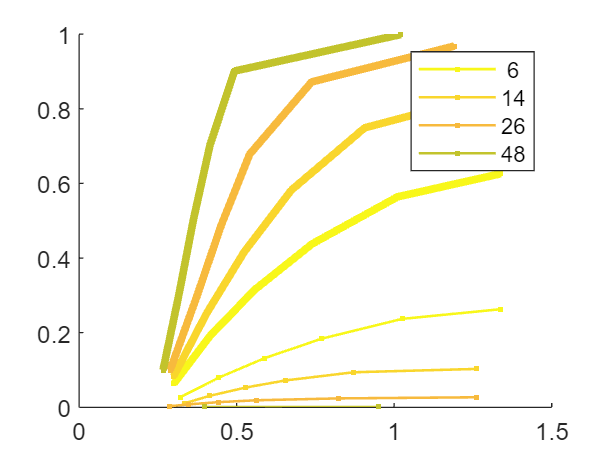

simdatsum = makeSummaryStructure(simdata,qps,0);
plotdatsum(simdatsum)

Looks like its working, so let's do the fit.

First define parameter ranges - the minimum and maximum values each parameter can take. It's helpful for it to know the bounds in parameter space within which it should stay. For example, a parameter like non-decision time, assuming we define it as sensory and motor transmission delays, would be expected to be positive so we can set 0 as the lower bound for that (though in some other situations you might have reason to believe accumulation starts ahead of time; we'll assume not here). At the same time, delays totalling more than 0.5 sec seems far fetched so that can be the upper bound. Drift rate, in the context of this simple task, is also not going to be negative, given we are setting the model up so that the upper bound means correct and the lower means error. 

Be liberal and use wide ranges. This is guided by playing around with parameters above, but often you might come back and revise if it seems that it might converge quicker with a more limited parameter space, or if you find that the best fitting parameters include ones that are right at the very limit of what you have allowed it to take in par_range, then come back and expand it.

See the simulation function for definitions of these parameters and how they're used to implement the model:

% Define parameter ranges: 
par_range = [0 0.5;... % tnd 
            0 0.5;... % d(1) drift rate for lowest coherence
            0 0.5;... % d(2) drift rate for 2nd coherence
            0 0.5;... % d(3)
            0 0.5;... % d(4)
            0 0.5;... % b bound
            -0.25 0.5]; % y bound collapse slope - allowing it to increase over time, if that's what it needs to do to fit data

Now we set up and run the search algorithm for all the model versions we want to test and compare. Let's say we want to run 4 models in this order:

1) constant bounds and one drift rate free parameter (3 free parameters)

2) constant bounds but with 4 free drift rate parameters (6 free parameters)

3) time-varying bounds and one drift rate free parameter (4)

4) time-varying bounds but with 4 free drift rate parameters (7)

modelfn = 'simul_2AFCddm'; % name of function that will be called by G2 to generate predicted data
modelnames = {'ConstBnd_1d','ConstBnd_4d','CollBnd_1d','CollBnd_4d'};
% for each, designate which will be free to vary to fit data
Selvecs = {[1 1 0 0 0 1 0], [1 1 1 1 1 1 0], [1 1 0 0 0 1 1], [1 1 1 1 1 1 1]};
pm_if_fixed = [nan nan nan nan nan nan 0]; % order: [tnd d(x4) b y] any parameter that needs to be fixed at a certain value if not free to vary? Just y=0 for const bound
N=1000; % the more trials simulated per condition, the more accurate the G^2, AIC etc, and less specific to the happenstance of the particular noise generating by the rng. Keeping it relatively low for this tutorial so doesn't take all day
tic
for m=1:length(modelnames)
    disp(modelnames{m})
    Sel = Selvecs{m};
    options = optimoptions('particleswarm','UseParallel',true, 'SwarmSize', 10*sum(Sel));
    [p,g2(m)] = particleswarm(@(p) G2(p,pm_if_fixed(Sel==0),Sel,datsum,qps,modelfn,N,seed), sum(Sel), par_range((Sel==1),1)',par_range((Sel==1),2)', options);
    bestpm(m,Sel==1) = p; bestpm(m,Sel==0) = pm_if_fixed(Sel==0); 
    if all(Sel(2:5)==[1 0 0 0])
        % In the case of one free drift rate parameter,have to fill in the other drift rates:
        bestpm(m,3)=bestpm(m,2)*cohlevels(2)/cohlevels(1); bestpm(m,4)=bestpm(m,2)*cohlevels(3)/cohlevels(1); bestpm(m,5)=bestpm(m,2)*cohlevels(4)/cohlevels(1);
    end
    disp(['best parameters: ' num2str(bestpm(m,:))])
    numfreepm=sum(Sel);
    
    % Do a fresh simulation of many trials with new noise, for computing AIC/BIC:
    g2new(m) = G2(p,pm_if_fixed(Sel==0),Sel,datsum,qps,modelfn,20000,sum(clock)); % note fresh seed and 20,000 trials per condn
    AIC(m) = g2new(m) + 2*numfreepm;
    BIC(m) = g2new(m) + numfreepm*log(sum(datsum.n(:)));
end

ConstBnd_1d


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


best parameters: 0.43667    0.017935    0.041848    0.077718     0.14348    0.061882           0


ConstBnd_4d


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


best parameters: 0.44665   0.0039545    0.024494    0.079299     0.15261    0.059531           0


CollBnd_1d


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


best parameters: 0.40282    0.015128    0.035298    0.065554     0.12102    0.094964    0.038954


CollBnd_4d


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


best parameters: 0.39691  0.00067382    0.042559    0.068018     0.13098    0.096433     0.04154


toc % good to keep track of how long it takes, in case you want to explore ways of making it more efficient, e.g. increasing the step size, changing particleswarm settings

Elapsed time is 95.718823 seconds.


So you should be able to pick out the 'best' model from the list of AIC and BIC values:

AIC

AIC =    91.2602   90.0244   48.5452   54.9978


You can plot each to take a look. Here I'll use the same plotting function of the cumulative quantiles, but you can also generate more detailed plots of the RT histograms, where it's easier to see finer features of its shape, etc.

BIC

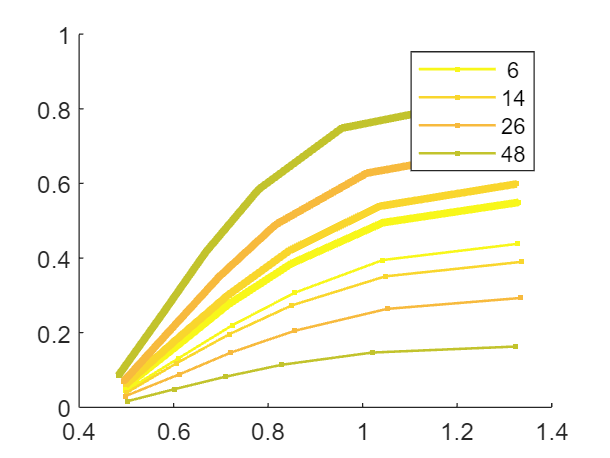

Sel = [1 1 0 0 0 1 1]; % the 3rd model for example
simdata = simul_2AFCddm(bestpm(3,Sel==1),pm_if_fixed(Sel==0),Sel,10000,seed);
simdatsum = makeSummaryStructure(simdata,qps,0);
plotdatsum(simdatsum)

Now what? You should be wondering, how do I know that these are THE best fitting parameter values possible? Well at minimum, you should run it more than once and see whether the answer ends up consistent. For the above 'light touch' code I found it was very inconsistent, so I would explore whether consistency is improved when I use larger numbers of simulated trials N, or if I increase the number of particles (currently set at 10*numfreeparams). There are other settings for the particleswarm function to explore also, like maximum evaluations and tolerances (when does it know to stop searching?). Two things to look out for:

BIC and AIC might give different conclusions. This is because BIC penalises more stricty for additional free parameters than AIC does. Whether you should penalise more or less depends on the study, e.g. I went by AIC in Kelly et al (2021) because the whole point there was to allow the neural data contribute to how the brain is really performing the task, and we had a separate validation step where we could test predictions with the CPP.

The model with more flexibility, e.g. the 4 free drift rates, might land at worse G^2 values than with one drift rate and the scaling constrained by relaitve coherences. This is definitely a sign that the more complex model has not found its true best parameter vector, because INCLUDED in the possibilities for that vector, is the one found by the simpler model! There, it can be good to start the search for the more complex model STARTING a particle at the vector that was the best fit for the simpler model. I think this can be done with particleswarm, but fminsearchbnd could alternatively be used, which explicitly takes a starting parameter vector as input - included in this folder.

function plotdatsum(datsum)
figure; hold on
% colors for 4 coherences:
jt = parula; % a standard colour pallette
col = jt(fliplr(1:21:end),:);
lw = [1 3]; % line widths - error thin and correct thick
% We'll plot it in cumulative form, which is often done in the literature

for ce=1:2 % error and correct
    for c=1:4
        plot((datsum.q(1:end-1,ce,c)+datsum.q(2:end,ce,c))/2,cumsum(datsum.qp(:,ce,c)),'.-','Color',col(c,:),'LineWidth' ,lw(ce))% using the midpoint of the bins as the x-axis
    end
end
cohlevels = [6 14 26 48];
legend(num2str(cohlevels'))
end